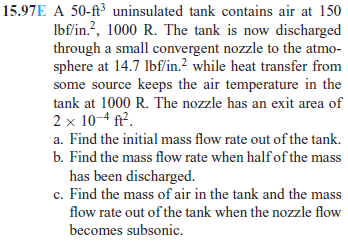

# given

u = symunit;
Vtank = 50*u.ft^3;
ptank = 150*u.psi;
Ttank = 1000*u.Rankine;
pb = 14.7*u.psi;
Ae = 2e-4*u.ft^2;
air = ig([], 'US');

# part A

% stagnation properties
po_A = ptank;
To_A = Ttank;
% cricial pressure
ps_A = po_A*air.p_po(1);
ps_A_vpa = vpa(ps_A, 4)

$$ps\_A\_vpa = 79.24\,\mathrm{psi}$$

% mass flow rate
Me_A = 1; % nozzle is choked for part A
pe_A = ps_A;
Te_A = To_A*air.T_To(Me_A);
Te_A_vpa = vpa(Te_A, 5)

$$Te\_A\_vpa = 833.33\,\mathrm{{}^{\circ}R}$$

Ve_A = rewrite(Me_A*sqrt(air.gamma*air.R*Te_A), 'US');
Ve_A = simplify(Ve_A, 'IgnoreAnalyticConstraints', true);
Ve_A_vpa = vpa(Ve_A, 6)

$$Ve\_A\_vpa = 1414.99\,\frac{\mathrm{ft}}{s}$$

rhoe_A = rewrite(pe_A/(air.R*Te_A), 'US');
rhoe_A_vpa = vpa(rhoe_A, 3)

$$rhoe\_A\_vpa = 0.257\,\frac{\mathrm{lbm}}{{\mathrm{ft}}^{3}}$$

mdot_A = rhoe_A*Ae*Ve_A;
mdot_A_vpa = vpa(mdot_A, 4)

$$mdot\_A\_vpa = 0.07265\,\frac{\mathrm{lbm}}{s}$$

# part B

% stagnation properties
po_B = 0.5*ptank;
po_B_vpa = vpa(po_B)

$$po\_B\_vpa = 75.0\,\mathrm{psi}$$

To_B = Ttank;
% cricial pressure
ps_B = po_B*air.p_po(1);
ps_B_vpa = vpa(ps_B, 4)

$$ps\_B\_vpa = 39.62\,\mathrm{psi}$$

% mass flow rate
Me_B = 1; % nozzle is choked for part B
pe_B = ps_B;
Te_B = To_A*air.T_To(Me_B);
Te_B_vpa = vpa(Te_B, 5)

$$Te\_B\_vpa = 833.33\,\mathrm{{}^{\circ}R}$$

Ve_B = rewrite(Me_B*sqrt(air.gamma*air.R*Te_B), 'US');
Ve_B = simplify(Ve_B, 'IgnoreAnalyticConstraints', true);
Ve_B_vpa = vpa(Ve_B, 6)

$$Ve\_B\_vpa = 1414.99\,\frac{\mathrm{ft}}{s}$$

rhoe_B = rewrite(pe_B/(air.R*Te_B), 'US');
rhoe_B_vpa = vpa(rhoe_B, 4)

$$rhoe\_B\_vpa = 0.1284\,\frac{\mathrm{lbm}}{{\mathrm{ft}}^{3}}$$

mdot_B = rhoe_B*Ae*Ve_B;
mdot_B_vpa = vpa(mdot_B, 4)

$$mdot\_B\_vpa = 0.03632\,\frac{\mathrm{lbm}}{s}$$

# part C is too confusing!!!!!!!